**Project 12: Aircraft Descent Profile (Aerospace)**

Objective: Simulate altitude change during descent under speed constraints.

Core Tasks:

`•` Define an initial cruising altitude and target landing altitude.

`•` Simulate vertical descent rate while enforcing maximum and minimum speed constraints.

`•` Identify phases of descent (steady descent, leveling, final approach).

Key Deliverables:

`•` MATLAB script modeling altitude and vertical speed over time.

`•` Altitude vs. time and speed vs. time plots.

`•` Short explanation of how constraints influence the descent profile.

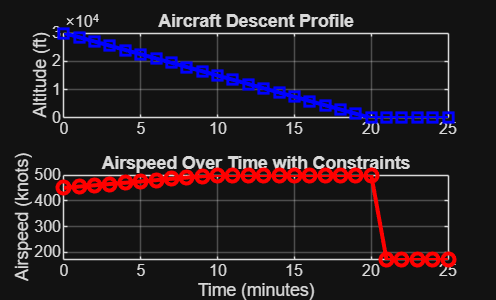

%% The Flight Parameters
altitude_cruise = 30000; % Starting altitude in feet
altitude_target = 0;     % Landing altitude (sea level)
descent_rate = -1500;    % Vertical speed in feet per minute (fpm)
t = 0:1:25;              % Time vector from 0 to 25 minutes
altitude = altitude_cruise + (descent_rate * t); % This Simulates Altitude Over Time
altitude = max(altitude, altitude_target); % This ensures altitude doesn't go below the target (0 ft)

% Airspeed Model with Constraints
% Airspeed naturally wants to increase during descent due to gravity,
raw_speed = 450 + (t * 5); 

% Constraint 1 shows Maximum Speed (Never exceed 500 knots for safety)
speed = min(raw_speed, 500); 

% Constraint 2 shows Minimum Speed
% As we get close to landing (after 20 mins), we slow down significantly.
speed(t > 20) = 170; 
speed = max(speed, 150); % Floor at 150 knots

% Flight Phases
% Using logical indexing to tag the data
phases = strings(size(t));
phases(altitude > 25000) = "Steady Descent"; % Phase 1 shows a steady descent in altitude
phases(altitude <= 25000 & altitude > 5000) = "Leveling/Intermediate"; % Leveling between the altitudes
phases(altitude <= 5000) = "Final Approach"; %Phase before landing 

%% 5. Visualization
figure; % The First Figure
subplot(2,1,1); % Top plot 
plot(t, altitude, 'b-s', 'LineWidth', 2); % Plots the altitude and time 
grid on; % Allows for grid lines
ylabel('Altitude (ft)'); % Labels the y axis for altitude 
title('Aircraft Descent Profile'); % Labeles the graph 
% Plot Speed
subplot(2,1,2); % Bottom plot 
plot(t, speed, 'r-o', 'LineWidth', 2); %Plots the time and airspeed on the axises 
grid on; % Allows for grid
xlabel('Time (minutes)'); % Displays Time on the X axis 
ylabel('Airspeed (knots)'); % Displays Airspeed on the Y axis 
title('Airspeed Over Time with Constraints'); % Provides a title for the graph 